## Race Strategy Pit Lap Optimisation.

Consider a 50 lap race with a single compound of tyre available and a mandatory pit stop, what is the optimum lap to pit for fresh tyres for a given tyre wear and fuel correction model?

Assumption of degradation per lap: Fuel corrected laptime increases non-linearly as tyre wears (non-linear tyre deg model estimate).

Fuel correction assumption for 110kg of fuel to last 50 laps and 0.035s laptime gain per 1kg of fuel burn.

Let's assume a pit stop takes 20 seconds to complete.

Calculating Fuel Correction Factor

fuelQuantity = 110;  %kg
totalLapNumber = 50; %laps
lapNumber = 1:50;
timePerKg = 0.035;   %seconds

fuelConsumption = fuelQuantity/totalLapNumber;   %kg/lap

fuelCorrectionFactor = fuelConsumption .* timePerKg; %seconds/lap

fuelLapCorrections = fuelCorrectionFactor .* (lapNumber-1);

Defining Tyre Wear Factor

tyreWear = linspace(0.08,0.17,50); %seconds

tyreAge = 1:50; %laps

Calculating Tyre Degradation Laptime Impact

initialLaptime = 95;   %seconds

tyreDegLaptime = initialLaptime + tyreWear .* (tyreAge-1);

Calculating Tyre and Fuel Effected Laptimes for Full Distance Tyre Model

laptime = initialLaptime + (tyreWear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);

% To determine fuel corrected laptimes for individual stints, the following 
% formula is appropriate:

% Fuel_Corrected_Stint_Formula = TyreDegLaptime(tyreAge(1:end_of_stint)) 
% - fuelLapCorrections(lapNumber(stint_start_lap:stint_end_lap))

Defining Average Pit Time Loss

pitTime = 20;  %seconds

Plotting the tyre model to visualise the tyre life and pace over the full race distance.

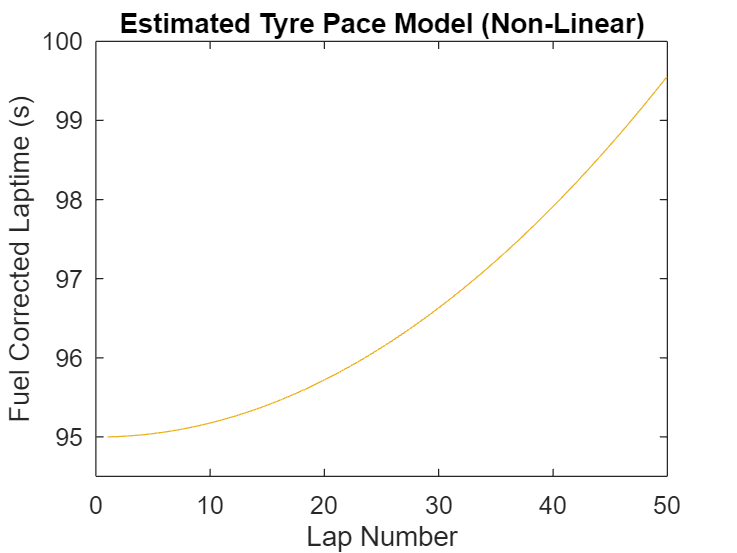

plot(lapNumber,laptime,"Color","#EDB120")
xlabel("Lap Number")
ylabel("Fuel Corrected Laptime (s)")
ylim([94.5 100])
title("Estimated Tyre Pace Model (Non-Linear)")

Defining the optimisation problem with objective function, variables and constraints.

% Objective (minimise over 50 laps) raceTime = total lap times (including pit time).

% Establish the logic such that we can choose to stop at any point, and 
% only once, at which point the tyreAge returns to 1. (Expect therefore the
% optimal stop to be at the half way point of the race).

prob = optimproblem("Description","Single_Tyre_Pit_Lap","ObjectiveSense","minimize");
pitLap = optimvar("pitLap",'Type','integer','LowerBound',1,'UpperBound',49);

% Calculating fuel corrected stints
%fuel_Corrected_Stint1 = laptime(tyreAge(1:pitLap));
%fuel_Corrected_Stint2 = tyreDegLaptime(tyreAge(1:(50-pitLap))) - fuelLapCorrections(lapNumber(pitLap+1:50));

%raceTimeTotal = sum(fuel_Corrected_Stint1) + sum(fuel_Corrected_Stint2) + pitTime  %seconds

raceTimeTotal = pitTime + int(calculateLapTime(initialLaptime,tyreWear,tyreAge,fuelLapCorrections,lapNumber),tyreAge,[1 pitLap]) + int(calculateLapTime(initialLaptime,tyreWear,tyreAge,fuelLapCorrections,lapNumber),tyreAge,[1 50-pitLap]);

Incorrect number or types of inputs or outputs for function 'int'.


prob.Objective = raceTimeTotal;

[sol,optval] = solve(prob);